# 2.1 数量と図形の大きさを紐づける

### 図 2.1.1 図形の大きさと数量を紐づける

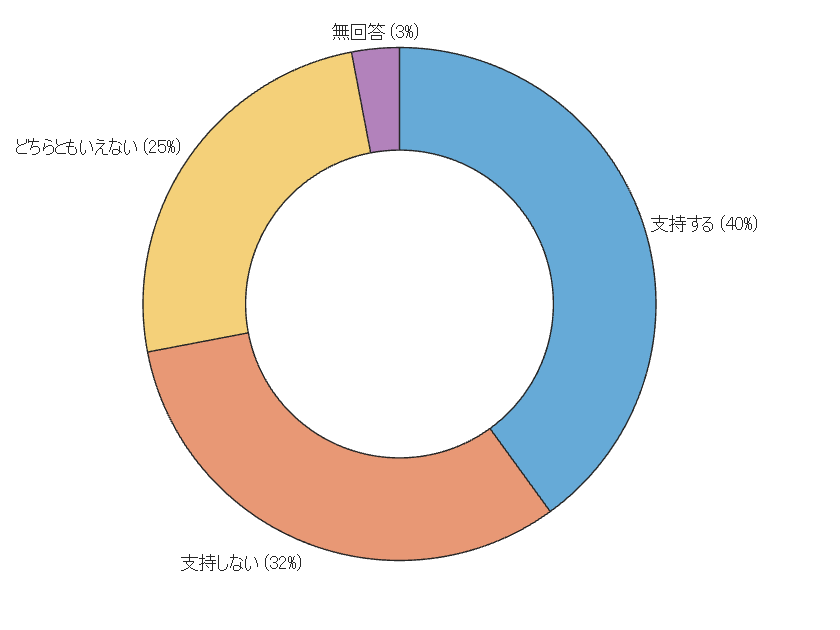

% Data in percentages
data = [40, 32, 25, 3];

% Labels
labels = {'支持する', '支持しない', 'どちらともいえない', '無回答'};

% Corresponding colors for each label
% colors = {'blue', 'red', 'lightgray', 'gray'};

% Sort data, labels, and colors by data in descending order
[~, sortedIdx] = sort(data, 'descend');
data = data(sortedIdx);
labels = labels(sortedIdx);
% colors = colors(sortedIdx);

donutchart(data,labels)

% Reduce the saturation of the colors
% MATLAB does not have a direct equivalent to mcolors.to_rgba, but you can manually adjust the alpha values.
% colors = cellfun(@(c) adjustColor(c, 0.6), colors, 'UniformOutput', false);

% Draw the donut chart
% figure; % Create a new figure
% h = pie(data, zeros(size(data))); % Create a pie chart with dummy zero vector for explode
% ax = gca;
% ax.Colormap = cell2mat(colors); % Apply the custom colors
% hold on;

% Convert the pie chart to a donut chart by overlaying a white circle
% Calculate the center and radius of the pie chart for the white circle
% pieCenter = get(h(1), 'Vertices');
% pieCenter = mean(pieCenter);
% radius = 0.3; % The white circle's radius (relative to the pie chart's radius)
% whiteCircle = rectangle('Position', [pieCenter(1)-radius, pieCenter(2)-radius, radius*2, radius*2], ...
                        % 'Curvature', [1, 1], 'FaceColor', 'w');

% Move the white circle below the pie chart slices
% uistack(whiteCircle, 'bottom');

% Adjust labels font size
% for i = 1:length(h)
    % if strcmpi(get(h(i), 'Type'), 'text')
        % set(h(i), 'FontSize', 20);
    % end
% end

% MATLAB automatically adjusts layout, so there is no direct equivalent to plt.tight_layout()
% saveas(gcf, '2_1_1_donut.png'); % Save the figure as a PNG image

% MATLAB figures are displayed by default, so there is no need for an equivalent to plt.show()


### 図 2.1.2 ワードクラウドを用いた「頻度と見た目の大きさ」の紐づけ

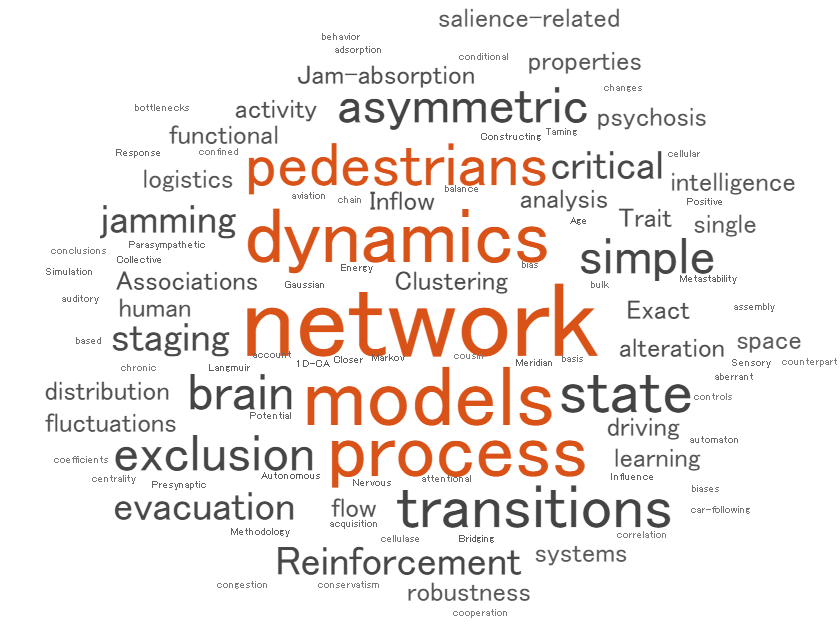

% Text data
text = "Clustering coefficients for correlation networks, Energy landscape analysis of neuroimaging data, Simulation of space acquisition process of pedestrians using proxemic floor field model, Pedestrian flow through multiple bottlenecks, Closer to critical resting-state neural dynamics in individuals with higher fluid intelligence, Reinforcement learning explains conditional cooperation and its moody cousin, Jam-absorption driving with a car-following model, Age‐related changes in the ease of dynamical transitions in human brain activity, Potential global jamming transition in aviation networks, Methodology and theoretical basis of forward genetic screening for sleep/wakefulness in mice, Jamming transitions in force-based models for pedestrian dynamics, Inflow process of pedestrians to a confined space, Exact solution of a heterogeneous multilane asymmetric simple exclusion process, Exact stationary distribution of an asymmetric simple exclusion process with Langmuir kinetics and memory reservoirs, Taming macroscopic jamming in transportation networks, A demonstration experiment of a theory of jam-absorption driving, A balance network for the asymmetric simple exclusion process, Reinforcement learning account of network reciprocity, Towards understanding network topology and robustness of logistics systems, Inflow process: A counterpart of evacuation, Analysis on a single segment of evacuation network, Dynamics of assembly production flow, Presynaptic inhibition of dopamine neurons controls optimistic bias, Bridging the micro-macro gap between single-molecular behavior and bulk hydrolysis properties of cellulase, Cluster size distribution in 1D-CA traffic models, Modelling state‐transition dynamics in resting‐state brain signals by the hidden Markov and Gaussian mixture models, Positive congestion effect on a totally asymmetric simple exclusion process with an adsorption lane, Metastability in pedestrian evacuation, Constructing quantum dark solitons with stable scattering properties, The Autonomous Sensory Meridian Response Activates the Parasympathetic Nervous System, Trait, staging, and state markers of psychosis based on functional alteration of salience-related networks in the high-risk, first episode, and chronic stages, Critical brain dynamics and human intelligence, Influence of velocity variance of a single particle on cellular automaton models, Collective motion of oscillatory walkers, Reinforcing critical links for robust network logistics: A centrality measure for substitutability, Dynamic transitions between brain states predict auditory attentional fluctuations, Associations of conservatism/jumping to conclusions biases with aberrant salience and default mode network, Model retraining and information sharing in a supply chain with long-term fluctuating demands, Functional alterations of salience-related networks are associated with traits, staging, and the state of psychosis.";
% Create a word cloud
figure; % Create a new figure
wordcloud(text); % Generate and display the word cloud
% title(''); % Remove title
% set(gcf, 'Color', 'white'); % Set background color to white

% Save the figure as a PNG image
% saveas(gcf, '2_1_2_wordcloud.png');

### 図 2.1.3 ツリーマップによるグループ情報の付与 (Todo)